# Classify Age of Brain MRI Study Participants using Deep Learning

This example shows how to apply transfer learning to tune a pretrained deep neural network (ResNet-18) to perform chronological age classification on a brain MRI dataset.

The study dataset contains 3D brain volumes and demographic data obtained from 155 study participants. To illustrate transfer learning using a lightweight deep network model (ResNet-18) pretrained with 2D image data, this example employs 2D axial midslice images extracted from each of the 3D volumes. It shows how ResNet-18 can be retrained to accurately classify these 2D brain images into three age group categories:

- Participants Aged 3-5

- Participants Aged 7-12

- Participants Aged 18 or older, classified as Adults

   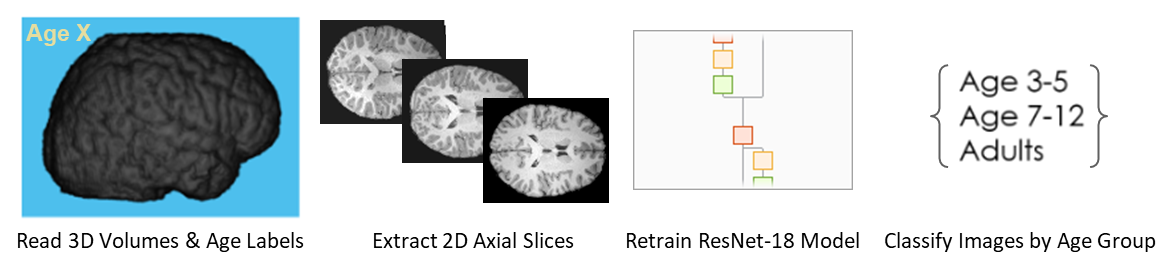

**Background on Dataset**

The anatomical MRI scans used in this example were obtained during a study [1] of social brain development conducted by researchers at the Massachusetts Institute of Technology (MIT) with expertise confronting the challenge of pediatric brain MRI imaging. The full study dataset, including functional MRI (fMRI) scans measuring the participants' brain activity, are available for exploration and download via the [OpenNEURO resource](https://openneuro.org/datasets/ds000228/versions/1.1.0).

**Background on Example**

This example uses a lightweight model, a smaller dataset (by deep learning standards), and a simplified task (ternary classification) to enable quick demonstration of a deep learning workflow using MATLAB with neuroimaging data. It is loosely illustrative of recent work suggesting deep learning has potential to build regression models of healthy brain aging based on structural MRI images [2]. Researchers are exploring the clinical relevance of such models, e.g., to measure a patient's brain age, whose discrepancy from chronological age could serve as a biomarker of disease [3].

## Read OpenNEURO Dataset

This example includes selections from the OpenNEURO dataset comprising 3D anatomical MRI scans of the brain taken from the 155 study participants of various ages: 

mriRootDataFolder = 'ds000228-1.1.0-subset';

In order to facilitate comparison between these brains of varying sizes and taken with differing MRI scanner protocols, the MIT researchers have also shared *preprocessed *brain volumes which are size-normalized and aligned to the Montreal Neurological Institute (MNI) template. These were computed using the freely available [Statistical Parametric Mapping (SPM) software](https://www.fil.ion.ucl.ac.uk/spm/software/) [4]. This example will use this *derivative* dataset of preprocessed brain volumes:

mriDataFolder = fullfile(mriRootDataFolder, 'derivatives', 'preprocessed_data');

### Read 3D Volumetric Data

**Read Neuroimaging (NIfTI) Image File**

The 3D brain volumes are accessible as a [Neuroimaging Informatics Technology Initiative (NIfTI)](https://nifti.nimh.nih.gov/) formatted file that has been zipped for compression. The volume for each participant can be read directly via the function `niftiread: `

vol = niftiread(fullfile(mriDataFolder,"sub-pixar001","sub-pixar001_normed_anat.nii.gz"));

**Visualize Skull-Stripped Volume**

The dataset additionally includes a pre-computed *mask *identifying the location of the skull in the volume. This can be used to perform *skull-stripping *on the volume: 

mask = niftiread(fullfile(mriDataFolder,"sub-pixar001","sub-pixar001_analysis_mask.nii.gz"));
vol = int16(vol) .* int16(mask); % Apply skull-stripping

Skull-stripping the volume reveals the outer surface of the brain's cortical surface. This can be visualized using `volshow`: 

numSlices = size(vol,3);
volshow(vol(:,:,1:round(numSlices/2)));

### Read Participant Data

**Read Tabular Data**

The dataset also includes a tab-delimited text file providing demographic details about the study participants, including their age and other attributes such as handedness. Use [readtable](https://www.mathworks.com/help/matlab/ref/readtable.html) to extract the values from this text file into a table variable:

participantFilename = fullfile(mriRootDataFolder, 'participants.tsv');
participantData = readtable(participantFilename,'FileType','delimitedtext','VariableNamingRule','preserve');
head(participantData) % view the first entries in the participant table to illustrate the original dataset contents

     participant_id      Age      AgeGroup    Child_Adult    Gender    Handedness    ToM Booklet-Matched    ToM Booklet-Matched-NOFB    FB_Composite    FB_Group    WPPSI BD raw    WPPSI BD scaled    KBIT_raw    KBIT_standard    DCCS Summary    Scanlog: Scanner    Scanlog: Coil     Scanlog: Voxel slize    Scanlog: Slice Gap
    ________________    ______    ________    ___________    ______    __________    ___________________    ________________________    ____________    ________    __________

**View Summary Statistics**

The ages of the participants vary from 3 to 34. For this example, we will classify participants into 3 age categories:

participantData.AgeClass(participantData.Age >= 3 & participantData.Age < 6) = categorical("Ages3-5");
participantData.AgeClass(participantData.Age >= 7 & participantData.Age < 13) = categorical("Ages7-12");
participantData.AgeClass(participantData.Age >= 18) = categorical("Adults");

summary(participantData.AgeClass)


155x1 categorical

     Ages3-5          65 
     Ages7-12         57 
     Adults           33 
     <undefined>       0 


The dataset of 155 participants includes 65 children in the ages 3-5 class, 57 children in the ages 7-12 class, and 33 adults.

### Read 2D Image Data

This deep learning example will use 2D images extracted from each participant's 3D brain volume. The 2D images are *axial slices*, referring to slices taken when viewing the brain volume from the top-down. The function `prepare2DImageDataset `performs the 2D image extraction and also normalizes the images by intensity, so the ensuing image classification will focus on structural image features. 

**Extract Axial Slice Exemplars**

Calling `prepare2DImageDataset `on the source data folder returns the first 2D axial midslice image from the first participant file in each age class as exemplars:

exemplars = prepare2DImageDataset(mriDataFolder);

**View Axial Slices by Age Class**

View these 2D image exemplars side-by-side and ordered by age class: 

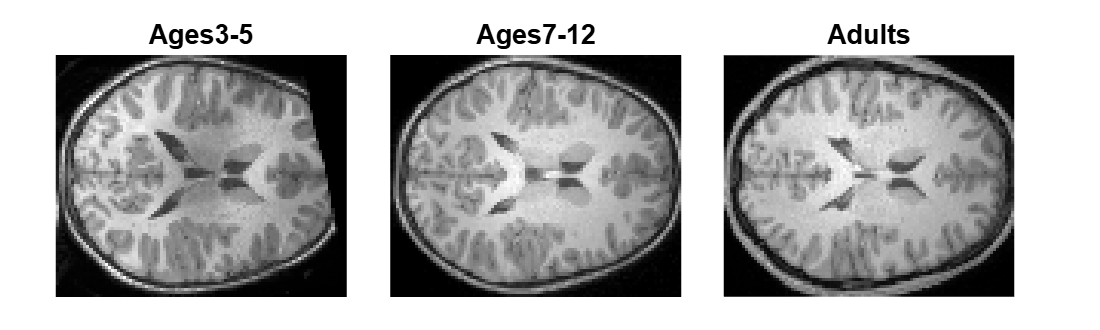

ageClasses = string(categories(participantData.AgeClass));

figure('Position',[10 10 500 150]);
tiledlayout(1,numel(ageClasses),'Padding','none','TileSpacing','none');

for ii=1:length(ageClasses)
    nexttile;
    imshow(mat2gray(exemplars{ii}));
    title(ageClasses((ii)));
end

These exemplars include the skull along with the brain for each subject image, and it can be clearly observed the brain-to-skull distance increases with each age class. Published literature indicates that brain volume and head circumference both increase during early childhood, but the brain volume decreases from adolescence onward while head circumference does not [6]. Thus, brain-to-skull distance is an obvious image feature that a human could readily learn and use to perform the age classification task. 

For this example, *skull stripping* will be applied for each of the MRI images. This will compel the network to learn less obvious features, not readily learned by a human, to distinguish between age classes. The published dataset includes a skull-stripping *mask* computed by SPM software [2] for each of the derived 3D volumes.

## Prepare Dataset for Deep Learning

### Extract, Normalize, and Augment 2D MRI Images

To prepare the dataset for deep learning, the function `prepare2DImageDataset` will be applied to all participant 3D brain volumes. 

Specify a destination folder, where the extracted and normalized 2D images will be stored: 

classifierDataFolder = "2DImageSet_"+string(datetime("now","Format", "ddMMMuuuu_HHmmss" ));

Specify the `prepare2DImageDataset `options`, `to apply skull-stripping as described above and to apply online *data augmentation*`:`

applySkullStripping = true;
applyAugmentation = true;

*Data augmentation *enlarges the image dataset prior to training. The study dataset contains a total of 155 images, which is a rather small dataset for deep learning. Enlarging the image dataset can generally help to prevent a network from overfitting and memorizing the exact details of the training images. For small datasets especially, it can also avoid underfitting because of insufficient training data to achieve good model convergence. Enabling the `applyAugmentation` option doubles the dataset size by adding copies of the MRI sections flipped 180 degrees. Performing this dataset enlargement *prior* to training is referred to as *offline* data augmentation. Further below, additional data augmentation will be applied *during* training, referred to as *online *data augmentation.

Call `prepare2DImageDataset `with the specified options to create a 2D image set folder: 

prepare2DImageDataset(mriDataFolder, classifierDataFolder, applyAugmentation, applySkullStripping);

### Create Image Datastore and Visualize Images

This deep learning example employs *supervised* learning, which requires *labeled *training data. For the collection of 2D image files just produced, the subfolder names are the source of image labels, with images grouped into subfolders specifying the participant age category. 

Use an [`ImageDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html?s_tid=doc_ta) object to conveniently represent and manage this collection of labeled 2D image files going forward. The `LabelSource` option is specified as `'foldernames'`:

mriImgds = imageDatastore(classifierDataFolder,'IncludeSubfolders',true,'LabelSource','foldernames','FileExtensions','.png');

`The shuffle` method for an` imageDatastore `object can be used to select a random image from each image class (age group):

mriImgdsRand = shuffle(mriImgds);
mriImgdsExamples = splitEachLabel(mriImgdsRand,int16(1)); % Select the firstmost image from the just-shuffled datastore for each age class
numLabels = length(mriImgdsExamples.Labels);

for ii=numLabels:-1:1
    [imgArray{ii},infoArray(ii)] = readimage(mriImgdsExamples,ii);
end

We can display these random selections from each age class to see how they compare side-by-side:

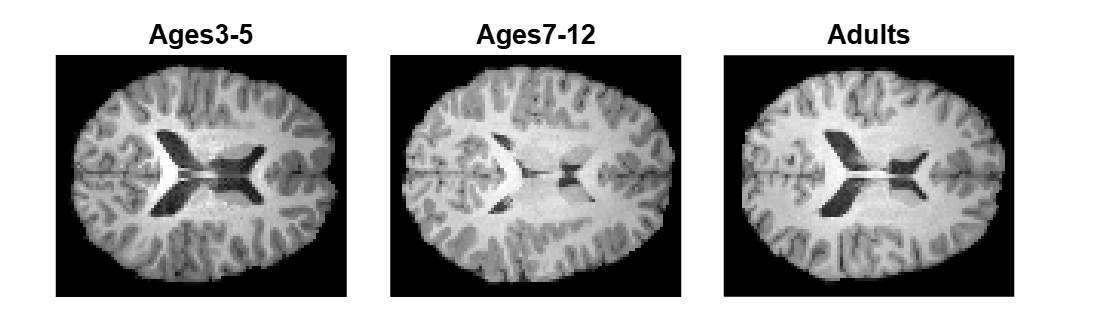

figure('Position',[10 10 500 150]);
tiledlayout(1,3,'Padding','none','TileSpacing','none');
for selCount=1:length(ageClasses)
    % Find the random-selected image in imageArray which pertains to the next age class for display
    idx = find(ageClasses(selCount) == [infoArray.Label]);
    
    % If image is a flipped image (from the offline data augmentation), then flip it back, so all images have the same orientation
    [~,fname] = fileparts(infoArray(idx).Filename);
    if startsWith(fname,'image2')
        img = imrotate(imgArray{idx},-180);
    else
        img = imgArray{idx};
    end
    
    % Show the random selected image for the next age class
    nexttile;
    imshow(mat2gray(img));
    title(infoArray(idx).Label);
end

Given the normalizations by image size and intensity as described above, no brain structural features obviously vary with age allowing one to readily distinguish between the age classes. 

The user is encouraged to verify this with additional randomized selections from each image set, to further demonstrate the lack of image features obviously suited for this classification task:

### Divide the Dataset for Training and Evaluation

Training a neural network requires the dataset be split between the:

- Training image set, to supply the network with images to learn the classification task during training

- Validation image set, to test the network's classification accuracy during training (online)

- Test image set, to test the network's classification accuracy and evaluate the network performance after training is completed (offline)

Use the [`splitEachLabel`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html?s_tid=doc_ta) function to divide the overall 2D midslice image set into these smaller image sets for training, validation, and testing. This is often done in two steps, beginning with the split creating the test image set: 

[trainImgs,testImgs] = splitEachLabel(mriImgds,0.85,'randomized'); % Reserve 15 percent of overall dataset for testing

The training image set is then further subdivided to reserve a portion for validation:

[trainImgs, valImgs] = splitEachLabel(trainImgs,0.8,'randomized'); % Reserve 20 percent of dataset available for training for online validation

These dataset splits are uniform across the three age classes. Of the total of 310 images from 155 participants, including the 2x offline data augmentation performed above, these splits result in the following image quantities:

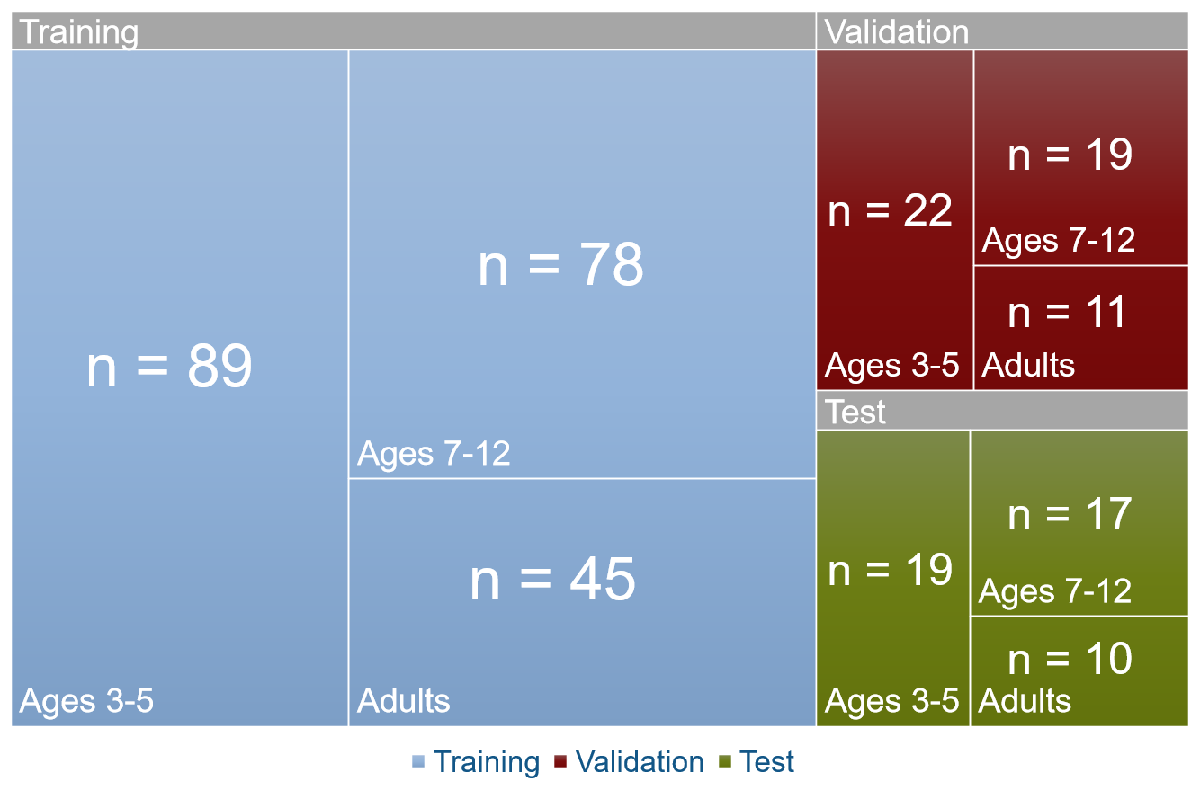

## Train ResNet-18 for Brain Age Classification

### Load the Pretrained Network

ResNet-18 is a convolutional neural network that is trained on more than a million 2D color images from the ImageNet database [[5]](https://www.mathworks.com/help/deeplearning/ref/resnet18.html#mw_591a2746-7267-4890-8390-87ae4dc7204c.mw_6dc28e13-2f10-44a4-9632-9b8d43b376fe). The network is 18 layers deep and can classify images into 1000 distinctive object categories, such as keyboard, mouse, pencil, and many animals. This network was not trained on any brain images nor for the task of discriminating ages among normalized brain MRI images.

Load the pretrained model, `resnet18`, which will prompt installation of the model support package on first usage. To naively apply the model to this new image type and new classification task, select one of the axial 2D midslice images and call `predict`. Note that input images may have sizes that are different from the pre-trained network's input layer. Use [`imresize`](https://www.mathworks.com/help/matlab/ref/imresize.html) to adjust the input image size.

[net, classnames] = imagePretrainedNetwork('resnet18');

netInputSize = net.Layers(1).InputSize;
inputImageSize = netInputSize(1:2);

img = imread(fullfile(classifierDataFolder,"Adults","image2_001.png"));
rimg = imresize(img, inputImageSize); % resize 2D brain image to match network's input image size

imgScore = predict(net, single(rimg));
imgLabel = scores2label(imgScore, classnames)

imgLabel = categorical
     chambered nautilus 


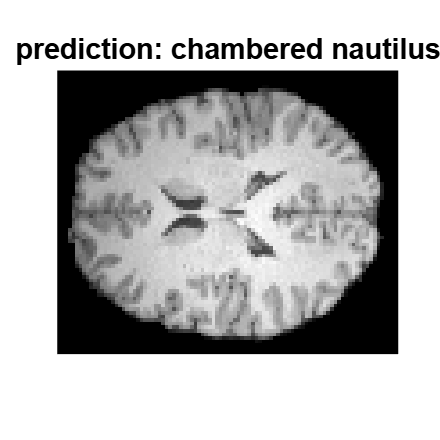


figure('Position',[10 10 200 200]);
imshow(img);
title("prediction: " + string(imgLabel));

The pretrained ResNet-18 network can only make predictions per the categories from its prior training. Commonly it will associate 2D brain slice images to the [chambered nautilus ](https://en.wikipedia.org/wiki/Chambered_nautilus)image category from its training set, which superficially shares some similar image features: a rounded shape with streaks originating from the periphery.

### Prepare Network for Transfer Learning

Transfer learning is a common deep learning approach in which a model that has been trained for one task is used as a starting point to train a model for a new task, e.g. to [classify a new set of images](https://www.mathworks.com/help/deeplearning/ug/train-deep-learning-network-to-classify-new-images.html). Fine-tuning a network with transfer learning is usually much faster and easier than training a network from scratch. Transfer learning works by repurposing the early layers of the pretrained network, which encode learning of the more general task, such as object recognition in 2D images.

Specific task learning is largely encoded in the last layers of the network. To retrain ResNet-18 to classify the 2D brain images by age group, use [`replaceLayer`](https://www.mathworks.com/help/deeplearning/ref/replacelayer.html) to change the last learnable network layer: the fully connected layer of the network. This layer is named `'fc1000'`. Set the new fully connected layer to have the same size as the number of classes in the new data set (3 in this example).

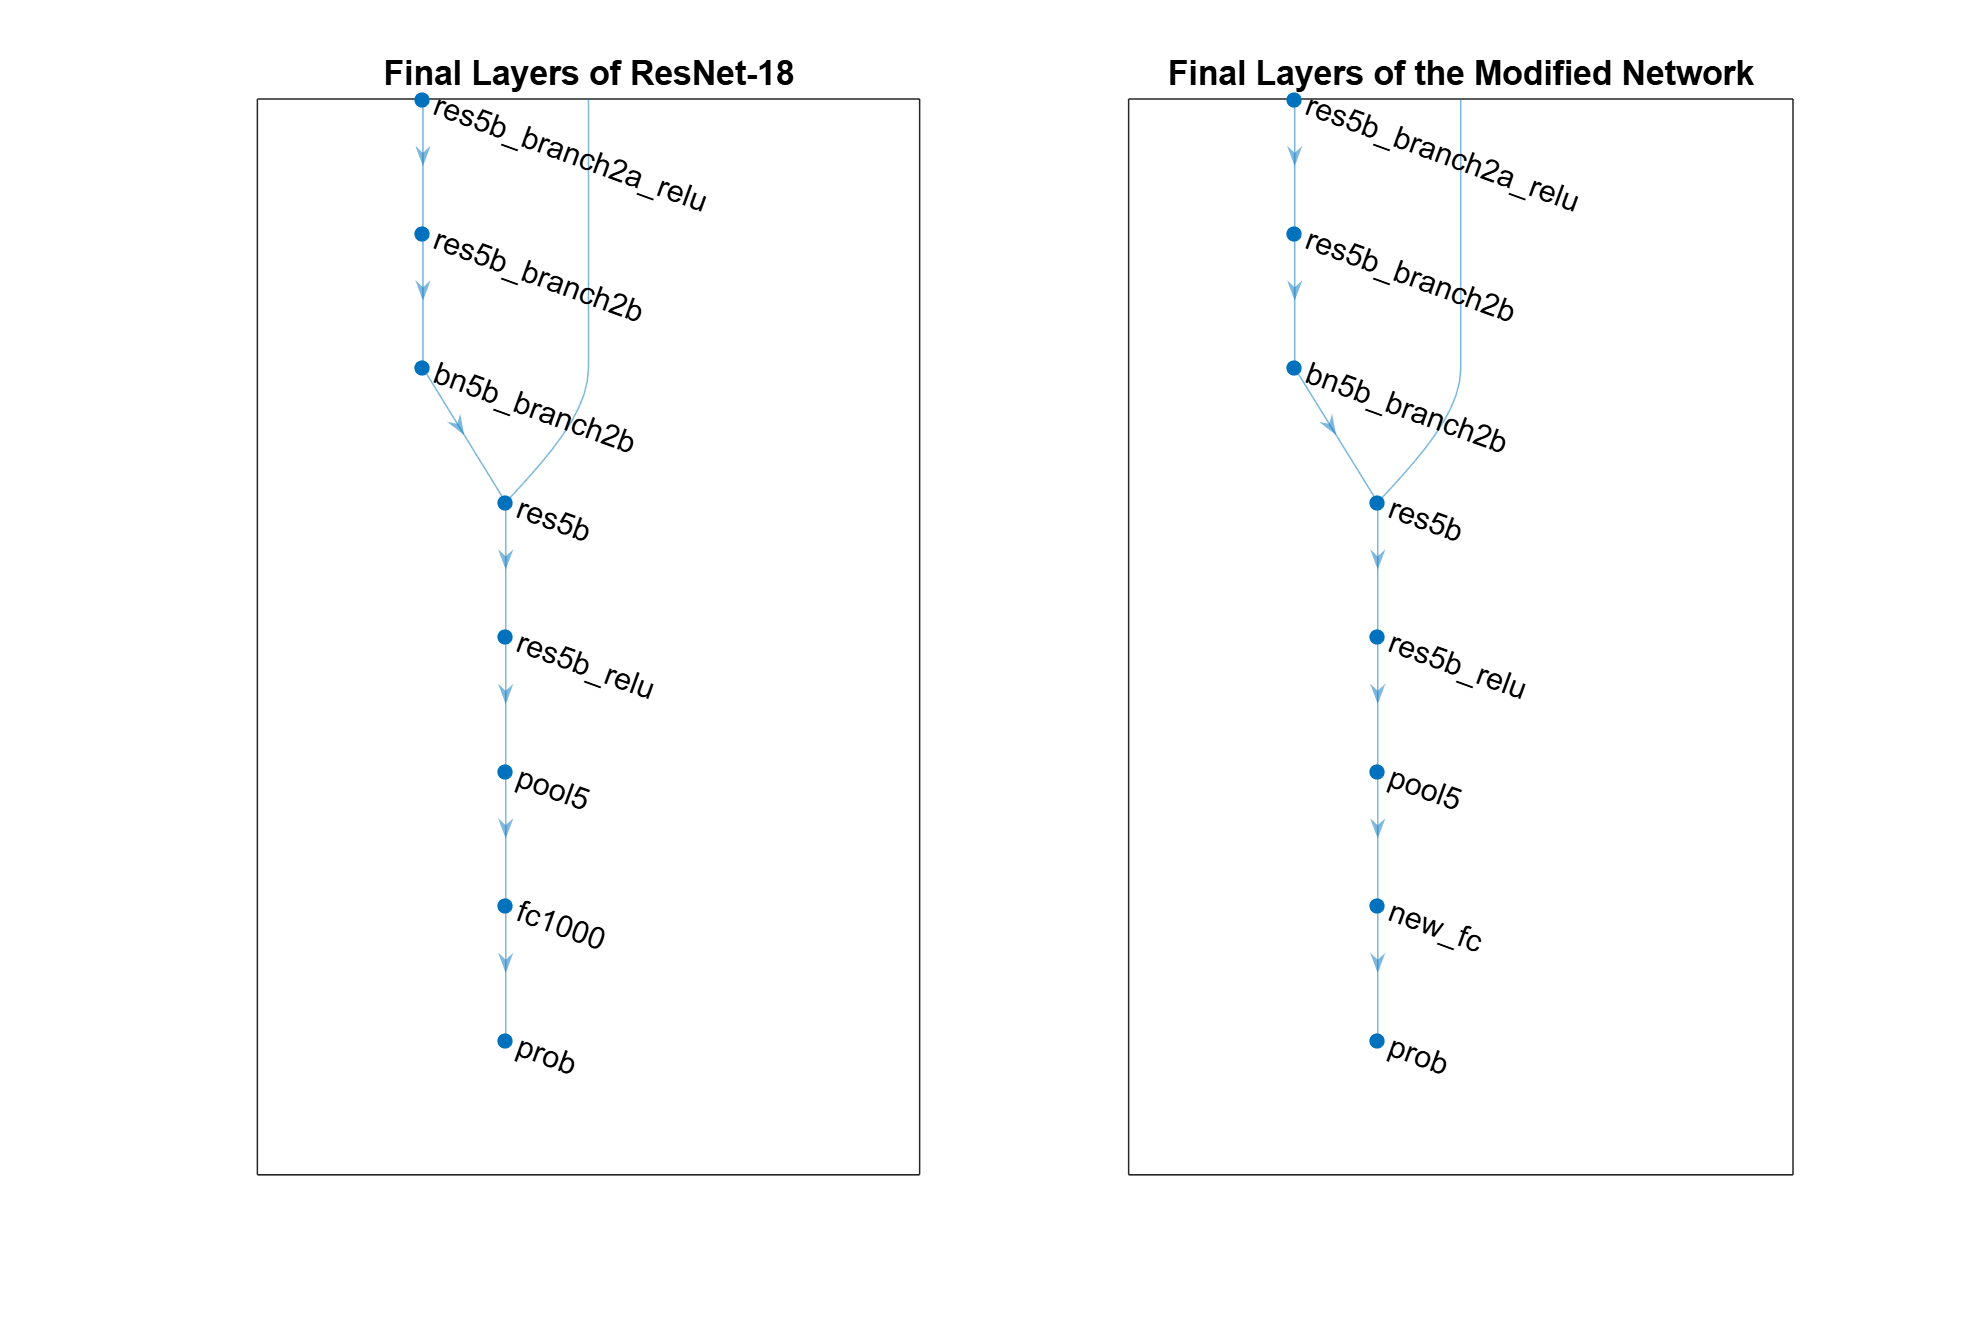

numClasses = numel(categories(mriImgds.Labels));

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
net_1 = replaceLayer(net,'fc1000',newLearnableLayer);


h = figure("Position",[10 10 900 600]);
subplot(1,2,1)
plot(net)
xlim ([0 4]); ylim([0 8])
title('Final Layers of ResNet-18')
subplot(1,2,2)
plot(net_1)
xlim ([0 4]); ylim([0 8])
title('Final Layers of the Modified Network')

### Resize Images and Apply Online Augmentation

Before training, it will be required to resize the dataset images to make them compatible with the input size of the deep learning network. Determine the desired size of images to match that expected by the neural network being trained. For a transfer learning setup, this input image size can be determined by reviewing the first layer of the pretrained network:

imageSize = net_1.Layers(1).InputSize(1:2);

An [`augmentedImageDatastore`](https://www.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html) can be used to dynamically resize the dataset images prior to training, validation, and testing operations during the deep learning workflow. As its name implies, it also provides the capacity to apply data augmentation operations, such as resizing, rotation, and reflection, to expose the network to a greater quantity and variety of images during training. This resizing and online data augmentation do not create any copies of the dataset files, in contrast to the offline image augmentation option above.

Load the images into 3 augmented image datastores - one each for the training image set, validation image set and test image set, with resizing applied uniformly for each. The option for data augmentation is applied by configuring and applying an imageDataAugmenter object: 

imageAugmenter      = imageDataAugmenter('RandRotation',[-30,30]); % Use randomized rotation for further data augmentation

datastore_train     = augmentedImageDatastore(imageSize,trainImgs,'DataAugmentation',imageAugmenter);
datastore_validate  = augmentedImageDatastore(imageSize,valImgs);
datastore_test      = augmentedImageDatastore(imageSize,testImgs);

disp(table({'Train';'Validate';'Test'},[datastore_train.NumObservations;datastore_validate.NumObservations;datastore_test.NumObservations],'VariableNames',{'Datastore','Image Count'}))

     Datastore      Image Count
    ____________    ___________

    {'Train'   }        212    
    {'Validate'}         52    
    {'Test'    }         46    



### Specify Training Options for Transfer Learning

Prior to beginning training, the [trainingOptions](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function can be used to configure the learning algorithm and process for the model. Some of the common parameters adjusted for transfer learning are:

- `InitialLearnRate`

- `MiniBatchSize`

- `MaxEpochs`

- `ValidationFrequency`

The default `InitialLearnRate` value is applicable for training a network from scratch. For transfer learning, the features learned by the pretrained model should be retained in the transferred layers. To accomplish this, the learning is slowed for all layers: 

Above, the `WeightLearnRateFactor` was set to 10 for the final (replaced) layer, so the model will learn this new image classification task at a typical rate. 

This demonstration example uses a smaller-sized dataset, with 106-212 training images. During each validation period (an *epoch*), the model is shown *mini-batches *of training images during each *iteration* of the learning algorithm. The `MiniBatchSize `is computed by dividing evenly (if possible) into the number of training images. In this way, the model is shown the whole training image set between each validation: 

valFrequency = 4; 
miniBatchSize   = floor(numel(datastore_train.Files)/valFrequency); % rounding needed in case offline data augmentation is disabled 

To speed the training demonstration for this example, the number of epochs will be reduced by 2x. The  [trainingOptions](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function creates and returns a training options object based on these parameters:   

options = trainingOptions("sgdm", ...
    InitialLearnRate = 0.001, ... % reduced 10x; compensated at final layer by WeightLearnRateFactor=10 above
    MaxEpochs = 15, ... % reduced by 2x
    MiniBatchSize = miniBatchSize, ...
    ValidationData = datastore_validate, ...
    ValidationFrequency = valFrequency, ...
    Plots = "training-progress", ...
    Metrics = "accuracy", ...
    Verbose = false, ...
    InputDataFormats="SSCB", ...
    Shuffle="every-epoch");

### Train the Network

By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, it uses a CPU.

if canUseGPU()
    gpudev = gpuDevice; % Use the default GPU device, if there's more than one
    reset(gpudev);
end

Train the network with the training image set.  

[mriNet,~] = trainnet(datastore_train, net_1, 'crossentropy', options);

As the training progresses, the accuracy steadily increased. The validation accuracy, checked every 4 iterations, generally tracks the training accuracy, which reassures the network is not being overfit, i.e., learning specific training images rather than generalizable features identified from those training images. 

At the final iteration of training, it is typical to see a notable change (typically a drop-off) in the final validation accuracy. For networks containing batch normalization layers, such as the ResNet-18 model used here, the [final validation metrics often differ](https://www.mathworks.com/help/deeplearning/examples/monitor-deep-learning-training-progress.html) from the values computed during training. This is because the network undergoes a finalization step after the last iteration to compute the batch normalization layer statistics for the entire training data rather than only the current mini-batch [7]. This effect could be reduced by increasing the size of the mini-batches, to better match the entire dataset statistics; but this would increase the computational cost for each iteration. 

## Perform Brain Age Classification with Trained Network

Classify the test dataset images using the trained network: 

test_scores = minibatchpredict(mriNet,datastore_test);
test_preds = scores2label(test_scores, categories(trainImgs.Labels));

This returns the predictions (`test_preds`) of brain age classes, as well as the confidence of the network (`scores`) for each prediction. 

### Determine Network Accuracy

How well did the network do? This accuracy can be computed by comparing the predictions to the test dataset labels:

accuracy = mean(test_preds == testImgs.Labels)

accuracy = 0.8478

Accuracies obtained will vary, given the randomized data split before training and data presentation during training. High accuracy levels (e.g., >80%) are typically obtained, which not only exceed that of chance (33%) but also the likely performance of a human classifier faced with the same task and training data. 

### Compute Confusion Matrix

Use a [`confusionchart`](https://www.mathworks.com/help/deeplearning/ref/confusionchart.html) to create a confusion matrix identifying which label were correctly predicted. This can help to identify where the network struggles the most within the test image set.

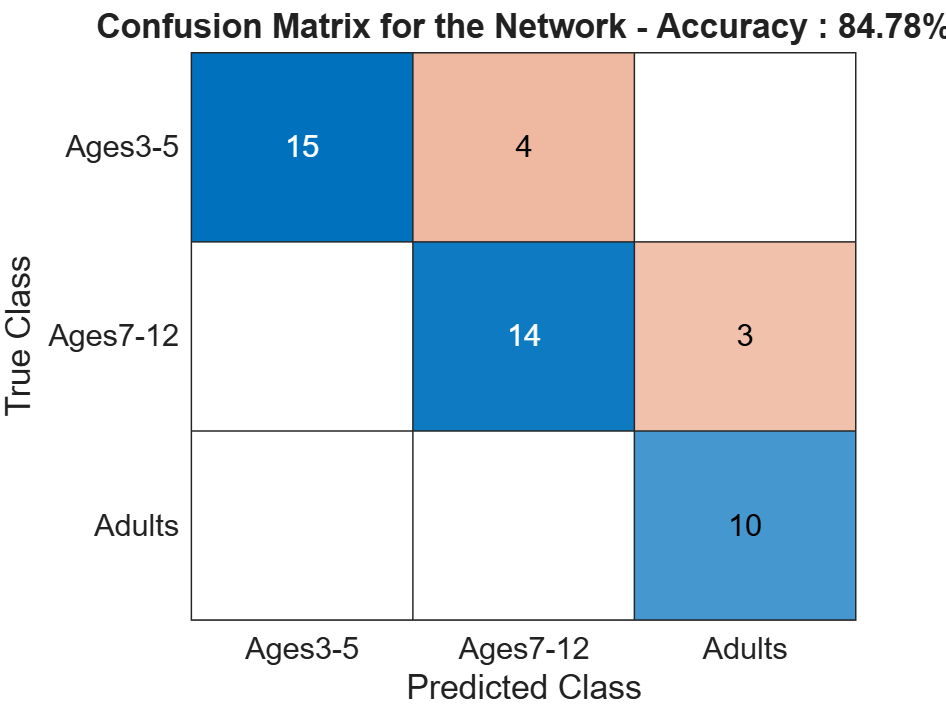

figure;
cm = confusionchart(testImgs.Labels,test_preds);
sortClasses(cm,["Ages3-5","Ages7-12","Adults"])
cm.Title = "Confusion Matrix for the Network - Accuracy : " + round(100*accuracy,2) + "%";

Across randomized training runs, some typical patterns are seen:

- Errors are nearly always only off-by-one class, i.e., it is quite rare to see an off-diagonal corner element where an adult is classified as a young child or vice versa. 

- It is also rare to see any errors in the top row, i.e., the children aged 3-5 are typically all correctly classified. 

These tendencies suggest the images of the youngest brains may contain the most distinctive features from the perspective of the network, as further explored in the next section. 

## Evaluate the Trained Network

To understand how a trained network achieves good accuracy, network visualization techniques, such as class activation and occlusion sensitivity maps, can be used to identify which locations, and perhaps image features, are most influencing the network's predictions. For instance, the ResNet-50 pretrained model can accurately identify images containing the French horn musical instrument, and occlusion sensitivity mapping suggests that it does so by honing in on the instrument's [distinctive valves and valve slides](https://blogs.mathworks.com/deep-learning/2017/12/15/network-visualization-based-on-occlusion-sensitivity/). 

### Visualize Features Used by Network via Occlusion

Occlusion sensitivity maps are computed by obstructing portions of the input image and observing its effect on the classification to determine which portions of the image are important in making the given prediction [8]. The [occlusionSensitivity](https://www.mathworks.com/help/deeplearning/ref/occlusionsensitivity.html) function computes these maps given a trained network and a set of test images.  

The local helper function viewOcclusionSensitivityMaps computes and displays occlusion sensitivity maps for correctly classified test images from a specific age class. For instance, display the occlusion sensitivity maps for a random selection of 3 correctly classified test images from the Ages3-5 class: 

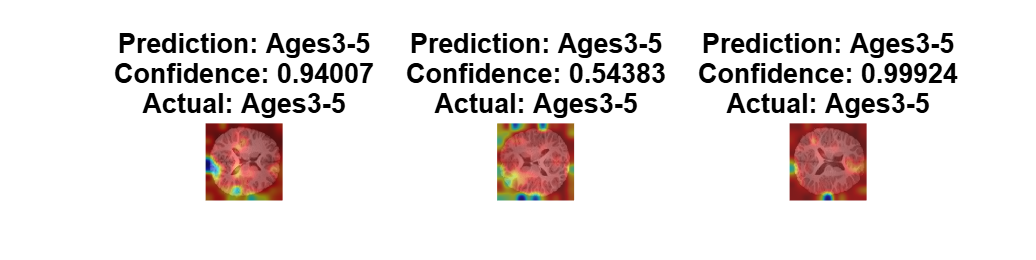

viewOcclusionSensitivityMaps("Ages3-5",3, mriNet, testImgs, test_preds, test_scores);

For classifying the youngest age class, the network typically reports very high confidence, consistent with the high accuracy observed. Often the occlusion sensitivity map will show the network is attuned to one or a few local brain features. These are often near the *ventricles* (channels for cerebrospinal fluid transport) at the center of each brain image. 

For comparison, the occlusion sensitivity maps can also be visualized for the two older age classes:

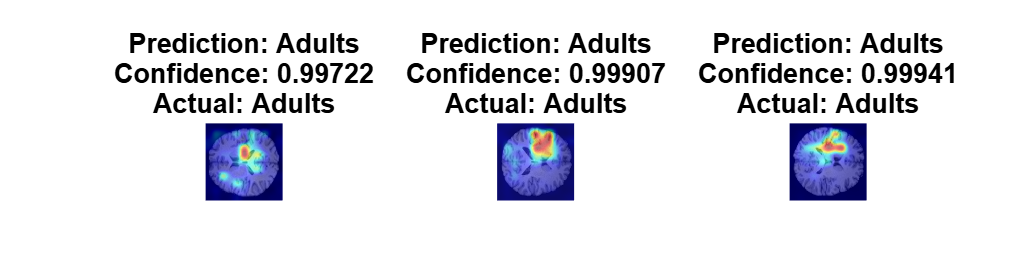

ageClass = categorical("Adults");
numSelections = 3;
viewOcclusionSensitivityMaps(ageClass,numSelections, mriNet, testImgs, test_preds, test_scores);

For the older age classes, the model's reported confidence is sometimes lower, and features are less often found to be localized. The network appears to take into account image features across the brain, including the central ventricles, the paracentral regions of *white matter *(axons connecting cortical regions), and the *grey matter regions *(the cortical folds) towards the edge of the brain volume. Each of these regions may have aspects which change with age, and a more advanced model trained on a larger dataset (e.g., using the full 3D volume, including more participants, and/or incorporating more imaging modalities) could conceivably take each carefully into account. 

## References

[1] Richardson, H., Lisandrelli, G., Riobueno-Naylor, A., & Saxe, R. (2018). Development of the social brain from age three to twelve years. Nature Communications, 9(1), 1027. [https://doi.org/10.1038/s41467-018-03399-2](https://doi.org/10.1038/s41467-018-03399-2)

[2] Cole, J.H., Poudel, R.P.K., Tsagkrasoulis, D., & Caan, M. (2016). Predicting brain age with deep learning from raw imaging data results in a reliable and heritable biomarker. Neuroimage, 163, 115. [https://doi.org/10.1016/j.neuroimage.2017.07.059](https://doi.org/10.1016/j.neuroimage.2017.07.059) 

[3] Cole, J.H. & Franke, K. (2017). Predicting age using neuroimaging: innovative brain ageing biomarkers. Trends in Neurosciences, 40(12), 681. [https://doi.org/10.1016/j.tins.2017.10.001](https://doi.org/10.1016/j.tins.2017.10.001)

[4] Friston, K.J., Holmes, A.P., Worsley, K.J, *et al *(1994). Statistical parameteric maps in functional imaging: a general linear approach. Human Brain Mapping, 2(4), 189. [https://doi.org/10.1002/hbm.460020402](https://doi.org/10.1002/hbm.460020402) 

[5] *ImageNet*. [http://www.image-net.org](http://www.image-net.org)

[6] Bartholomeusz, H. H., Courchesne, E., & Karns, C. M. (2002). Relationship Between Head Circumference and Brain Volume in Healthy Normal Toddlers, Children, and Adults. *Neuropediatrics*, *33*(05), 239–241. [https://doi.org/10.1055/s-2002-36735](https://doi.org/10.1055/s-2002-36735)

[7] Li, X., Chen, S., Hu, X., & Yang, J. (2018). Understanding the Disharmony between Dropout and Batch Normalization by Variance Shift. Retrieved from [http://arxiv.org/abs/1801.05134](http://arxiv.org/abs/1801.05134) 

[8] Zeiler, M. D., & Fergus, R. (2014). Visualizing and Understanding Convolutional Networks. In Fleet D., Pajdla T., Schiele B., & Tuytelaars T. (eds.) Computer Vision -- ECCV 2014. ECCV 2014. Lecture Notes in Computer Science, vol 8689. Springer, Cham. [https://doi.org/10.1007/978-3-319-10590-1_53](https://doi.org/10.1007/978-3-319-10590-1_53)

## Helper Functions

function viewOcclusionSensitivityMaps(ageClass,nSelections, mriNet, testImgs, test_preds, test_scores)

figure("Position",[10 10 1000 250])

netInputSize = mriNet.Layers(1).InputSize;
inputImageSize = netInputSize(1:2);

% Create a randomized set of indices into the test image datastore
selectionIdxs = randperm(length(testImgs.Files));

% Visualize a random selection of correctly predicted images for each age class
tiledlayout('flow'); % up to 5 selections per row

selCount = 1;
mapCount = 1;
while mapCount <= nSelections
    selIdx = selectionIdxs(selCount); % A randomly-selected image in the test image set
    currLabel = testImgs.Labels(selIdx);
    
    if currLabel == ageClass && currLabel == test_preds(selIdx) % Selected image is of the specified age class and has been correctly classified
        img = imresize(testImgs.readimage(selIdx),inputImageSize);
        scoreMap = occlusionSensitivity(mriNet, img, 1);
        
        nexttile;
        imshow(img);
        hold on
        imagesc(scoreMap,'AlphaData',0.5); % Overlay the score map onto the image with transparency
        
        colormap jet
        title([ ...
            "Prediction: " + string(test_preds(selIdx)) ,...
            "Confidence: " + num2str(max(test_scores(selIdx,:))) , ...
            "Actual: " + string(testImgs.Labels(selIdx))], ...
            'Interpreter', 'none');     
        
        mapCount = mapCount + 1; 
    end
    
    selCount = selCount + 1;
end

end

*Copyright 2020-2021 The MathWorks, Inc.*